## Biogas production neural network NARX modeling and training

More info about NARX model in Matalb docs

(https://uk.mathworks.com/help/deeplearning/modeling-and-prediction-with-narx-and-time-delay-networks.html)

There are 100 separate timeseries (samples) of 160 timesteps each with 3 inputs features and 2 targets

(timestep, Cow, Pig, Poultry, CH4, NH4)

% Read data from csv file generated from python script
raw_data = readmatrix('data\biogas_data_static.csv');

% We must now separate each timeseries (batch) and
% store them to a cell array
num_samples = 100;
timesteps = 160;

% Cell array to store all samples
inputs = cell(num_samples,1);
targets = cell(num_samples,1);

for i=1:num_samples
    start = (i-1)*timesteps+1;
    stop = i*timesteps;
    inputs{i} = tonndata(raw_data(start:stop,2:4),false,false);
    targets{i} = tonndata(raw_data(start:stop,5:6),false,false);
end

% Now we concatanete all samples to a single input and target cell array
% with the proper matlab format (timestep, feature, batch)
x = catsamples(inputs{:});
t = catsamples(targets{:});

% Create a NARX neural network
inputDelay = [1:4];
outputDelay = [1:4];
layerSize = 10;
feedbackMode = 'open';
trainFcn = "trainlm";

net = narxnet(inputDelay,outputDelay,layerSize,feedbackMode,trainFcn);
view(net)


% prepare timeseries for training
[Xs,Xi,Ai,Ts] = preparets(net,x,{},t);

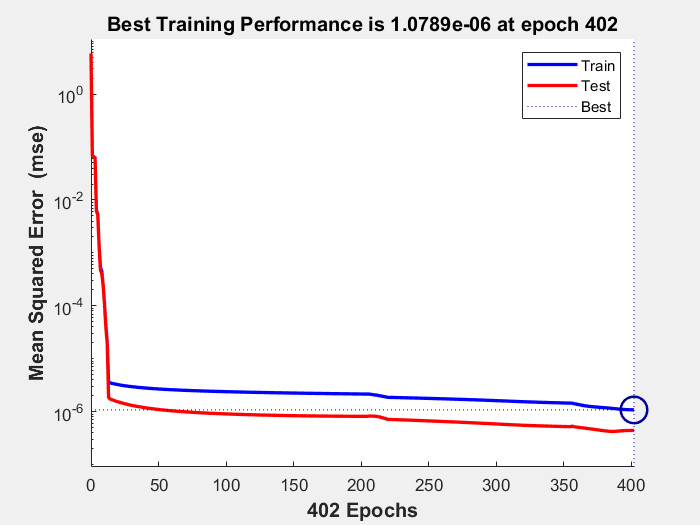

% Train the network
% 'net' is the resulting network object
% 'tr' is the training object holding training info
[net,tr] = train(net,Xs,Ts,Xi,Ai);

% Plot the training performance
plotperform(tr);

% Calculate the performance using MSE
Y = net(Xs,Xi,Ai);
perfopen = mse(net,Ts,Y);

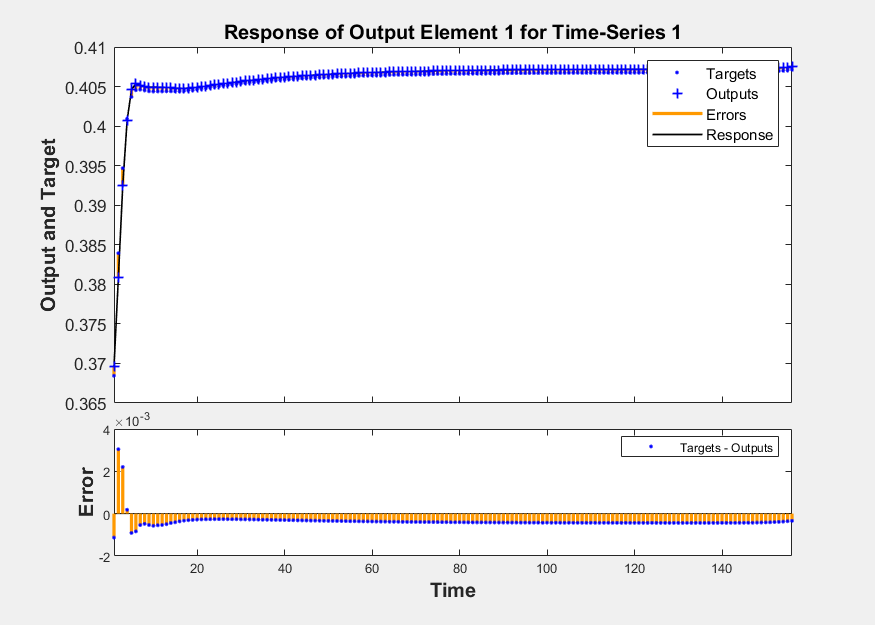

% Plot the response for CH4 (output 1) and NH4 (output 2)
% We can plot the responce for any sample, default is 1
plotresponse(Ts,Y,'outputIndex',1, 'sampleIndex', 1);

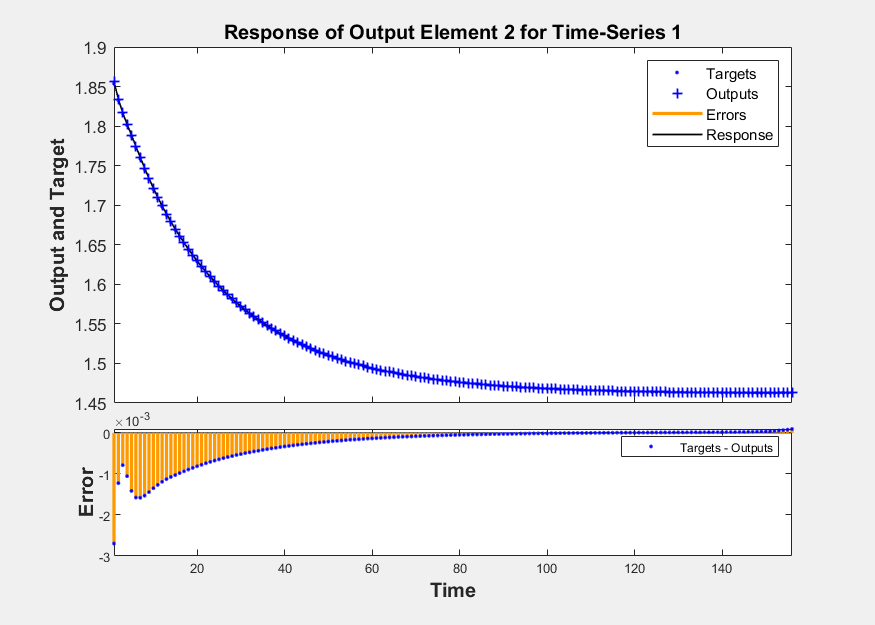

plotresponse(Ts,Y,'outputIndex',2, 'sampleIndex', 1);

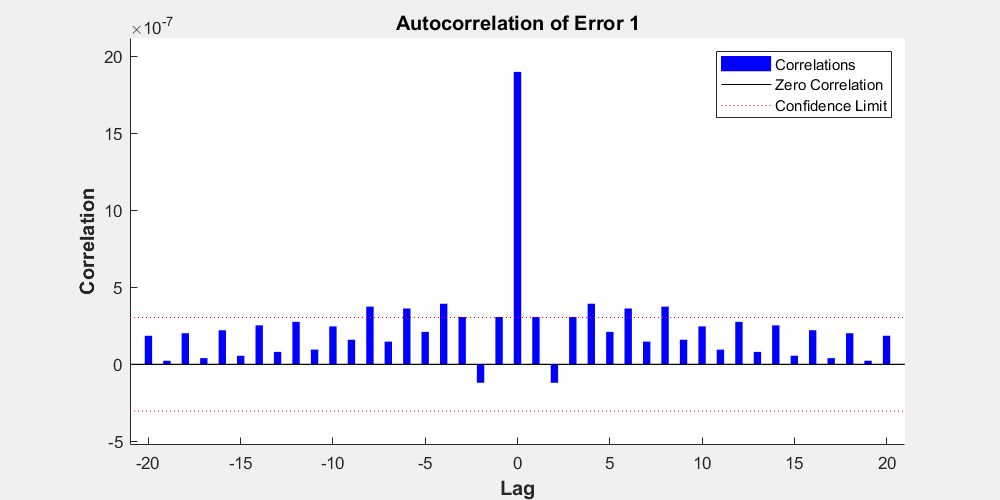

% PLOTERRCORR shows the correlation of error at time t, e(t) with errors over varying lags, e(t+lag).
% The center line shows the mean squared error.
% If the network has been trained well all the other lines will be much shorter,
% and most if not all will fall within the red confidence limits.

E = gsubtract(Ts,Y);
ploterrcorr(E,'outputIndex',1);

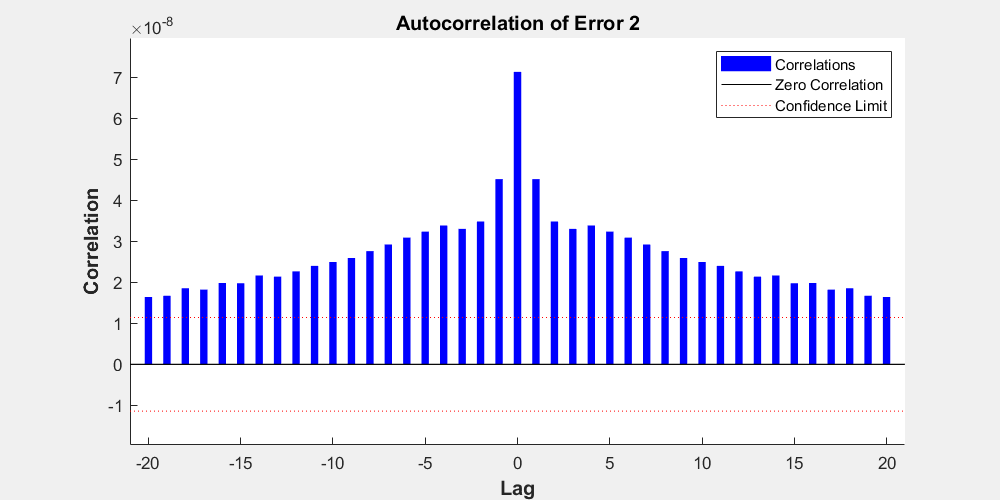

ploterrcorr(E,'outputIndex',2);

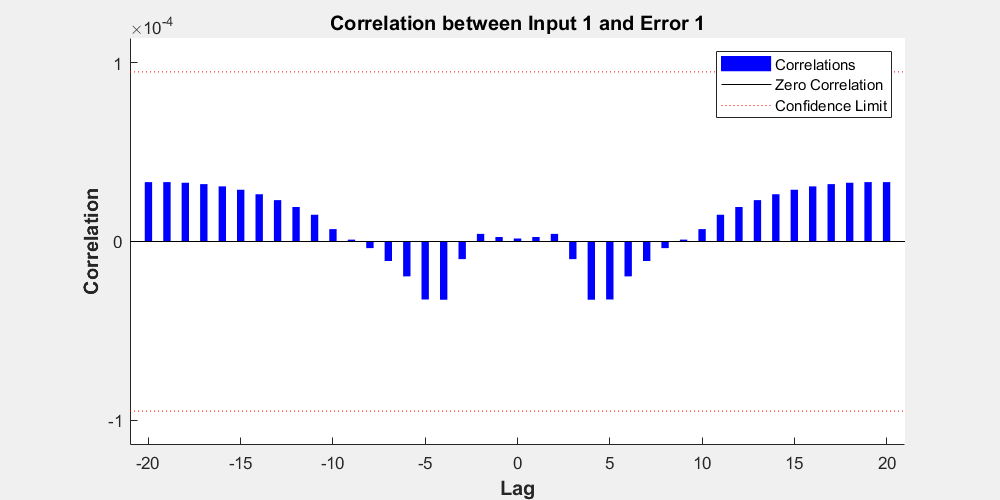

% Similarly, PLOTINERRCORR shows the correlation of error with respect to the inputs,
% with varying degrees of lag. In this case, most or all the lines should fall within
% the confidence limits, including the center line.
plotinerrcorr(Xs,E)

% The network was trained in open loop form, where targets were used as feedback inputs.
% The network can also be converted to closed loop form, where its own predictions become the feedback inputs.
net2 = closeloop(net);
view(net2)

% We can simulate the network in closed loop form.
% In this case the network is only given initial magnet positions,
% and then must use its own predicted positions recursively to predict new positions.
% This quickly results in a poor fit between the predicted and actual response.
% This will occur even if the model is very good. But it is interesting to see how many steps they match before separating.

[Xs,Xi,Ai,Ts] = preparets(net2,x,{},t);
Y = net2(Xs,Xi,Ai);
perfclosed = mse(net2,Ts,Y);

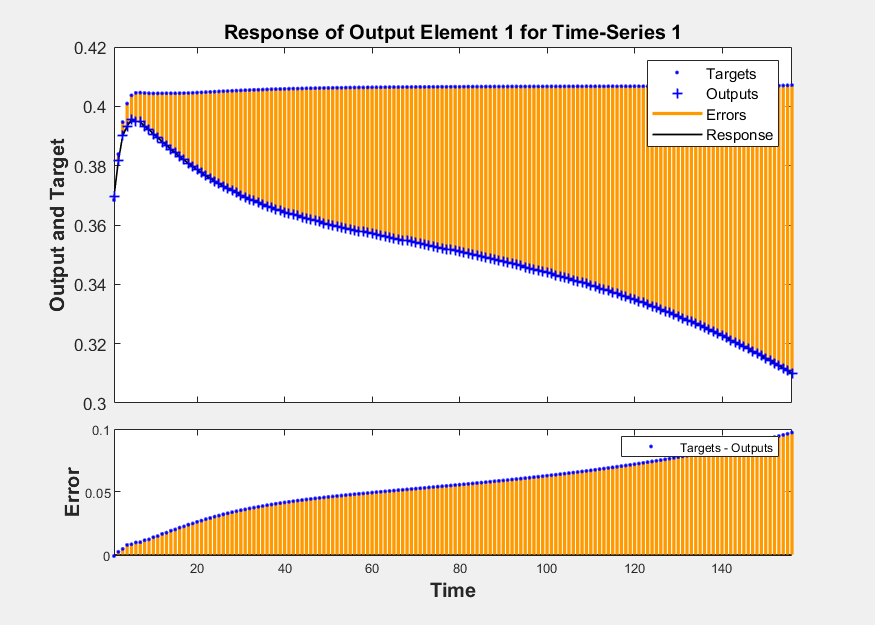

plotresponse(Ts,Y, 'outputIndex',1, 'sampleIndex', 1);

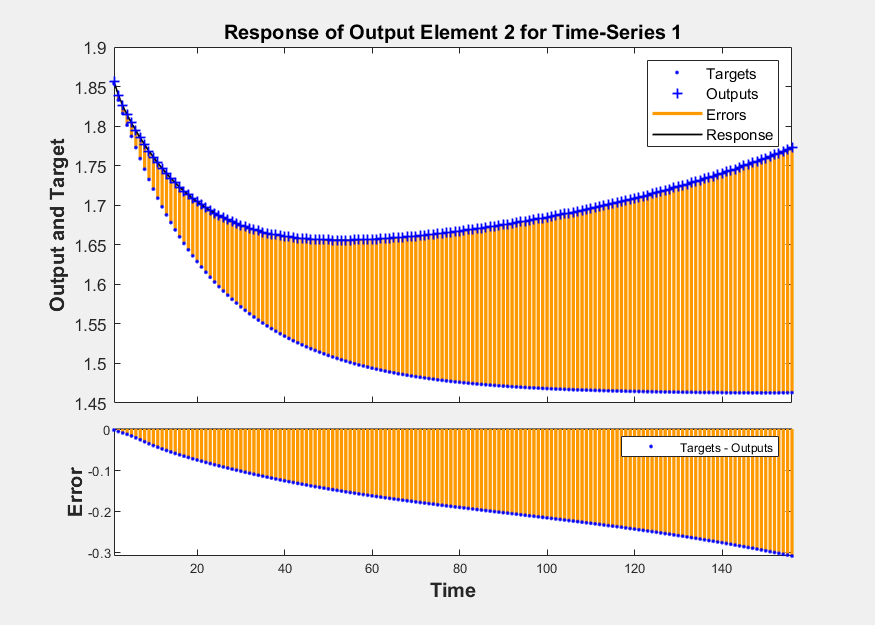

plotresponse(Ts,Y, 'outputIndex',2, 'sampleIndex', 1);

% Save the trained network for future use
save('trained_net','net');